# **Integrasi Numerik menggunakan metode Trapezoid dan Simpson**

**    Deskripsi Masalah**

    Reverse osmosis (RO) adalah teknologi yang digunakan untuk memurnikan air dengan melewatkannya melalui membran semi-permeabel yang menghilangkan ion, molekul, dan partikel lebih besar dari ukuran tertentu. Untuk memahami dan mengoptimalkan proses RO, penting untuk memprediksi konsentrasi solut dalam membran semi-permeabel. Model matematis yang sering digunakan untuk memprediksi konsentrasi ini melibatkan persamaan diferensial dan integral yang kompleks.

    Penelitian ini bertujuan untuk menyelesaikan model matematis sistem RO dengan menggunakan metode integrasi numerik, yaitu metode trapezoid, Simpson 1/3, dan metode Simpson 3/8, serta membandingkannya dengan solusi analitiknya. Hasil penelitian menunjukkan bahwa hasil integrasi numerik dengan metode trapezoid, Simpson 1/3, dan Simpson 3/8 memberikan hasil yang mirip dan mendekati solusi analitik. Metode Simpson 1/3 dan Simpson 3/8 memberikan hasil yang sedikit lebih akurat dibandingkan dengan metode trapezoid, namun perbedaannya tidak terlalu signifikan untuk kasus ini.

**Model Matematika**


$$C(x, 0) = \frac{3^{\frac{-1}{3}}qc_0}{DI}(\frac{Dh}{v_0})^{1/3}x^{\frac{1}{3}} + c_0$$


    Dalam konteks ini, konsentrasi C(x,0) dari larutan garam dalam membran semi-permeabel pada sistem RO diberikan oleh model matematika yang tertera di bawah, di mana q adalah laju aliran air dalam distribusi semi-permeabel, D adalah difusivitas garam dalam air, h adalah jarak dari batas semi-permeabel ke pusat saluran, C0 adalah konsentrasi jauh dari membran semi-permeabel, dan v0 adalah kecepatan aliran di permukaan membran.

**Fungsi Integrasi**


$$I = \int_0^\infty e^{-v^3}v dv$$


    Untuk menghitung solusi analitik lebih lanjut, kita perlu menyelesaikan integral dari I. Integral ini sulit untuk diselesaikan secara analitik, sehingga harus dihitung menggunakan metode numerik. Tiga metode integrasi numerik yang dipertimbangkan dalam penelitian ini adalah Trapezoid Rule, Simpson 1/3 Rule, dan Simpson 3/8 Rule. Masalah utama dalam penelitian ini adalah mengevaluasi akurasi dan efisiensi metode-metode integrasi numerik tersebut dalam menghitung nilai integral I dan membandingkan hasilnya dengan solusi analitik.

**Flowchart**

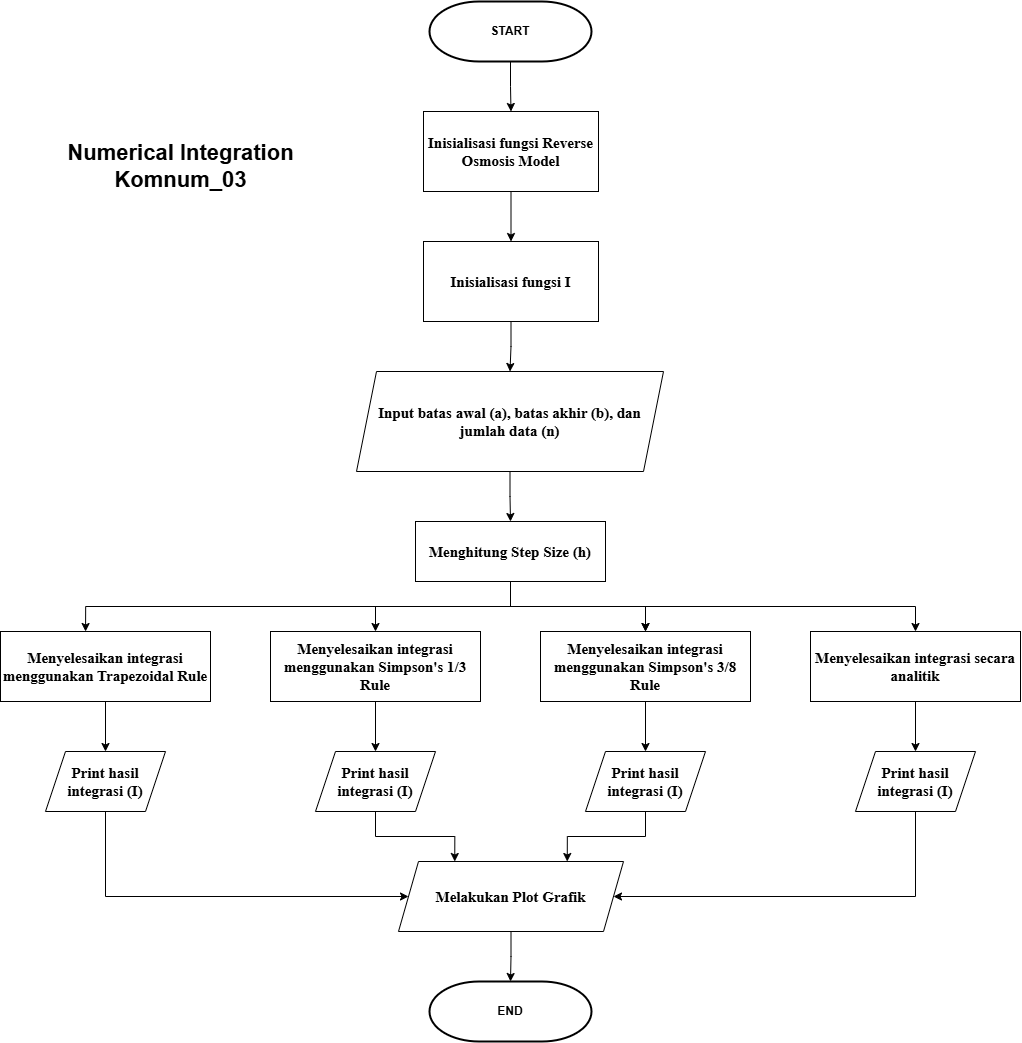

clear
clc

% Define Function
f = @(v) exp(-v.^3).*v; % Fungsi Analitik

% Define Bound and Segment 
input_lower = inputdlg("Masukkan batas bawah");
a = str2double(input_lower);

input_upper = inputdlg("Masukkan batas atas");
b = str2double(input_upper);

input_segment = inputdlg("Masukkan jumlah segmen");
n = str2double(input_segment);

step_size = (b - a) / n; % Step Size
x_values = a:step_size:b;
y_values = f(x_values);

% Perhitungan Analitik menggunakan Fungsi Integral
result = integral(f, a, b);

**Trapezoid Rule General Formula**


$$I = \int_a^bf(x) dx = \frac{h}{2}[f(x_0) + 2f(x_1) + ...+ 2(fx_{n-1}) + f(x_n)]$$


trapezoid_sum = 0.5 * (f(a) + f(b)); % Fungsi Awal dan Akhir
fprintf("Aproksimasi Metode Trapezoid");

Aproksimasi Metode Trapezoid

 for i = 1:n-1
   x = a + i * step_size;
   trapezoid_sum = trapezoid_sum + f(x);
   fprintf("%.6f\n", trapezoid_sum);
 end

0.184611
0.184611
0.184611
0.184611
0.184611


   total_trapezoid = step_size * trapezoid_sum; % Total Trapezoid

**Simpson's 1/3 Rule General Formula**


$$I = \int_a^b f(x) dx = \frac{h}{3}[(f(x_0) + f(x_n) + 4(f(x_1)+f(x_3) + f(x_5) + ... + f(x_{n-1}))+2(f(x_2)+f(x_4)+f(x_6)+...+f(x_{n-2})] $$


simpson_sum_3 = f(a) + f(b); % Fungsi Awal dan Akhir
fprintf("Aproksimasi Metode Simpson's 1/3");

Aproksimasi Metode Simpson's 1/3

for i = 1:n-1
    x = a + i*step_size;
    if mod(i, 2) == 0
        simpson_sum_3 = simpson_sum_3 + 2*f(x); % Genap
    else
        simpson_sum_3 = simpson_sum_3 + 4*f(x); % Ganjil
    end
    total_simpson_3 = simpson_sum_3 * step_size/3; % Total Integral
    fprintf("%.6f\n", total_simpson_3);
end

0.123521
0.123521
0.123521
0.123521
0.123521


**Simpson's 3/8 Rule General Formula**


$$I = \int_a^bf(x)dx = \frac{3h}{8}[(f(x_0) + f(x_n) + 3(f(x_1)+f(x_2) + f(x_4) +f(x_5)+ ... + f(x_{n-1}))+2(f(x_3)+f(x_6)+f(x_9)+...+f(x_{n-3})] $$


simpson_sum_8 = f(a) + f(b); % Fungsi Awal dan Akhir
fprintf("Aproksimasi Metode Simpson's 3/8");

Aproksimasi Metode Simpson's 3/8

for i = 1:n-1
    x = a + i*step_size;
    if mod(i,3) == 0
        simpson_sum_8 = simpson_sum_8 + 2*f(x); % Kelipatan 3
    else
        simpson_sum_8 = simpson_sum_8 + 3*f(x); % Sisanya
    end
    total_simpson_8 = ((3 * step_size)/8 * simpson_sum_8); % Total Integral
    fprintf("%.6f\n", total_simpson_8);
end

0.138710
0.138710
0.138710
0.138710
0.138710


**Plot Grafik Metode Analitik**

% Plotting Analytic
fprintf("Hasil dari metode Analitik : %.6f", result);

Hasil dari metode Analitik : 0.101476

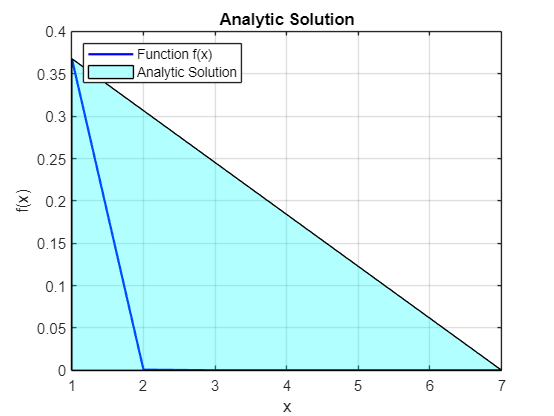

figure;
plot(x_values, y_values, 'b-', 'LineWidth', 1.5);
hold on;
fill([a, b, b, a], [0, 0, f(b), f(a)], 'c', 'FaceAlpha', 0.3);

% Plot settings
title('Analytic Solution');
xlabel('x');
ylabel('f(x)');
legend('Function f(x)', 'Analytic Solution', 'Location', 'NorthWest');
grid on;
hold off;

**Plot Grafik Aproksimasi Metode Trapezoid**

% Trapezoid Approximation
fprintf("Total metode Trapezoidal : %.6f", total_trapezoid);

Hasil dari metode Trapezoidal : 0.184611

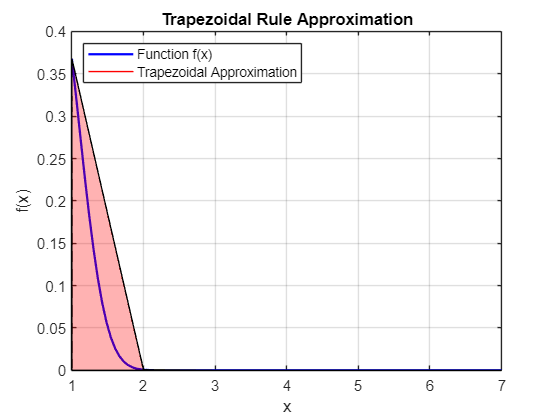


% Plotting the function and trapezoids
x_fine = linspace(a, b, 100);  % Fine grid for smooth function plot
y_fine = f(x_fine);

figure;
plot(x_fine, y_fine, 'b-', 'LineWidth', 1.5);
hold on;

% Plotting the trapezoids
for i = 1:n
    % Plot the edges of the trapezoid
    x1 = x_values(i);
    x2 = x_values(i+1);
    y1 = y_values(i);
    y2 = y_values(i+1);
    plot([x1, x2], [y1, y2], 'r-');
    
    % Plot the vertical lines of the trapezoid
    plot([x1, x1], [0, y1], 'k--');
    plot([x2, x2], [0, y2], 'k--');
    
    % Fill the trapezoid
    fill([x1, x2, x2, x1], [0, 0, y2, y1], 'r', 'FaceAlpha', 0.3);
end

% Plot settings
title('Trapezoidal Rule Approximation');
xlabel('x');
ylabel('f(x)');
legend('Function f(x)', 'Trapezoidal Approximation', 'Location', 'NorthWest');
grid on;
hold off;

**Plot Grafik Aproksimasi Metode Simpson 1/3**

% Simpson's 1/3 Rule Approximation
fprintf("Total metode Simpson 1/3 : %.6f", total_simpson_3);

Hasil dari metode Simpson 1/3 : 0.123521

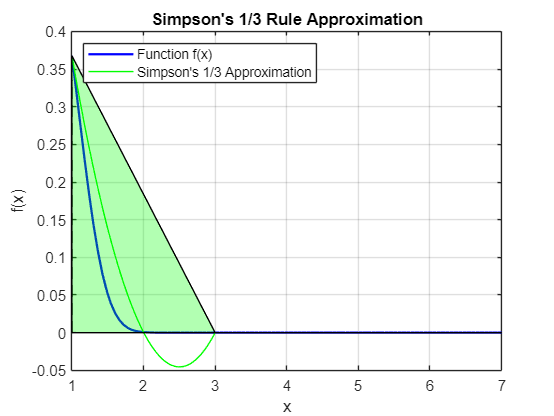

% Plotting Simpson's 1/3 Rule
figure;
plot(x_fine, y_fine, 'b-', 'LineWidth', 1.5);
hold on;

% Plotting Simpson's 1/3 segments
for i = 1:2:n-1
    % Plot the parabolic segments
    x_segment = x_values(i:i+2);
    y_segment = y_values(i:i+2);
    
    % Generate points for the parabolic curve
    x_parabolic = linspace(x_segment(1), x_segment(3), 100);
    y_parabolic = polyval(polyfit(x_segment, y_segment, 2), x_parabolic);
    
    plot(x_parabolic, y_parabolic, 'g-');
    
    % Plot the vertical lines of the segments
    plot([x_segment(1), x_segment(1)], [0, y_segment(1)], 'k--');
    plot([x_segment(3), x_segment(3)], [0, y_segment(3)], 'k--');
    
    % Fill the segment
    fill([x_segment(1), x_segment(3), x_segment(3), x_segment(1)], ...
         [0, 0, y_segment(3), y_segment(1)], 'g', 'FaceAlpha', 0.3);
end

% Plot settings
title('Simpson''s 1/3 Rule Approximation');
xlabel('x');
ylabel('f(x)');
legend('Function f(x)', 'Simpson''s 1/3 Approximation', 'Location', 'NorthWest');
grid on;
hold off;

**Plot Grafik Aproksimasi Metode Simpson 3/8**

% Plotting Simpson's 3/8 Rule
fprintf("Total metode Simpson 3/8 : %.6f", total_simpson_8);

Hasil dari metode Simpson 3/8 : 0.138710

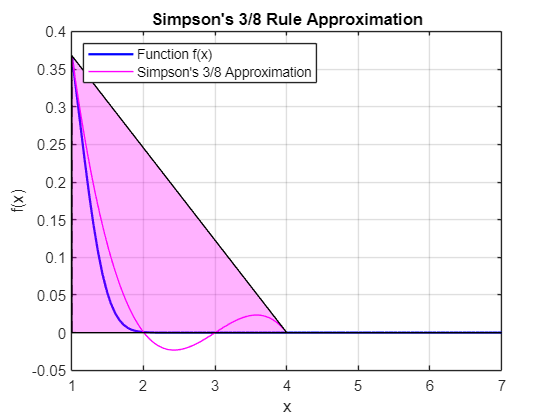

figure;
plot(x_fine, y_fine, 'b-', 'LineWidth', 1.5);
hold on;

% Plotting Simpson's 3/8 segments
for i = 1:3:n-2
    % Plot the cubic segments
    x_segment = x_values(i:i+3);
    y_segment = y_values(i:i+3);
    
    % Generate points for the cubic curve
    x_cubic = linspace(x_segment(1), x_segment(4), 100);
    y_cubic = polyval(polyfit(x_segment, y_segment, 3), x_cubic);
    
    plot(x_cubic, y_cubic, 'm-');
    
    % Plot the vertical lines of the segments
    plot([x_segment(1), x_segment(1)], [0, y_segment(1)], 'k--');
    plot([x_segment(4), x_segment(4)], [0, y_segment(4)], 'k--');
    
    % Fill the segment
    fill([x_segment(1), x_segment(4), x_segment(4), x_segment(1)], ...
         [0, 0, y_segment(4), y_segment(1)], 'm', 'FaceAlpha', 0.3);
end

% Plot settings
title('Simpson''s 3/8 Rule Approximation');
xlabel('x');
ylabel('f(x)');
legend('Function f(x)', 'Simpson''s 3/8 Approximation', 'Location', 'NorthWest');
grid on;
hold off;

**Kontribusi Anggota**

Kami mengerjakan dengan bersama-sama melalui aplikasi online. 

Namun untuk penanggungjawab memastikan bagian masing-masing beroperasi adalah:

- Julian Krisyairazy - ODE Flowchart & Coding

- Daffa Arbika - ODE Coding & Flowchart

- Fauzan Gusri - ODE LaTeX & Coding

- Annysa Hana Naadhirah - Integrasi Flowchart & Analisis Problem

- Alvin Hadar - Integrasi Flowchart & LaTeX

- Fauzan Chiryl - Integrasi flowchart 

- Farhan Nur Ardianto - Analisis problem & Coding

- Fadel Achmad - Integrasi Coding & LaTeX